# Phisiologycal signal classification (single signal)

## Load data

close all;clc;clearvars;
addpath(genpath('utils'));

in_dir = '../../data/EUSKALIBUR/hbm_physio_challenge/';
S = readtable([in_dir,'time_series.csv']);
annot = readtable([in_dir,'annotations.csv']);
clear in_dir;

### Time window

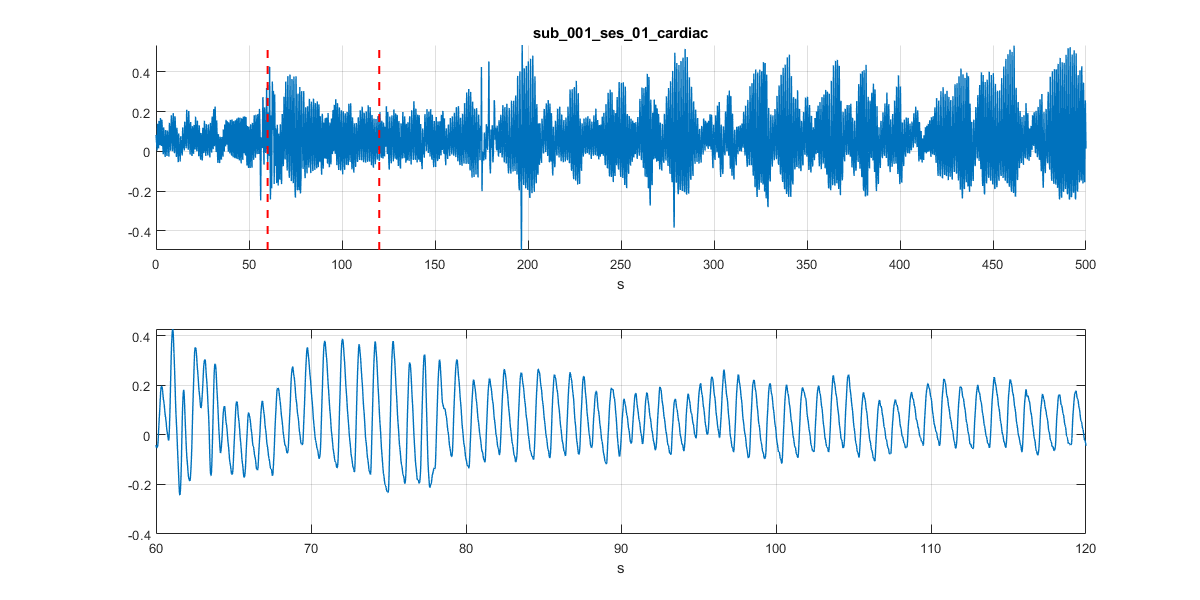

ind = 2;
s0 = S{:,ind};
n_samp = length(s0);
T = 1/100;  % Sampling period
t0 = 0:T:T*(n_samp-1);

t_start = 60;
t_end = 120;
[t, s] = crop_signal(t0, s0, t_start, t_end);

f = figure(2);clf;
set(f, 'Position',[0 0 1200 600]);

subplot(211); hold on;
plot(t0, s0, 'LineWidth', 1);xlabel('s'); title(annot.ts_name{ind},'Interpreter','none');grid on;
plot(t_start*[1 1], [min(s0) max(s0)], '--r', 'LineWidth', 1.5);
plot(t_end*[1 1], minmax(s0'), '--r','LineWidth', 1.5);
ylim(minmax(s0'));
subplot(212);plot(t, s, 'LineWidth', 1);xlabel('s');grid on;

### Smooth and normalize

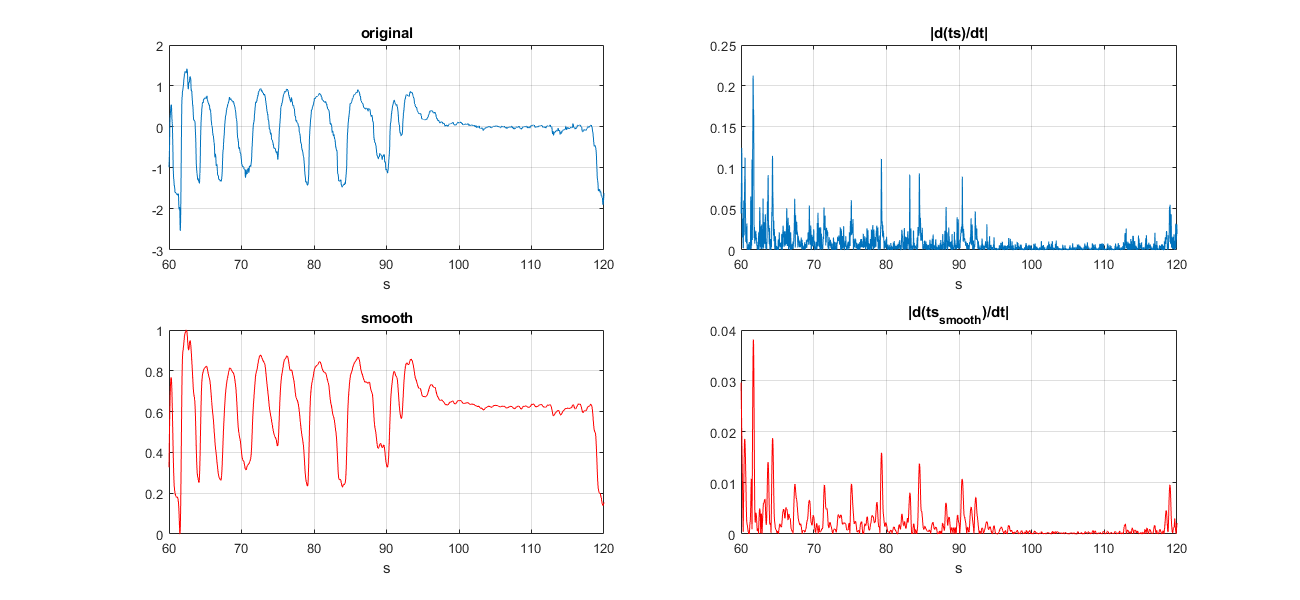

span = 0.011;

s1 = smooth(s, span, 'loess');
s1 = (s1 - min(s1))/(max(s1)-min(s1));

f = figure(2);clf;
set(f, 'Position',[0 0 1300 600]);
subplot(221); plot(t, s);xlabel('s');grid on;title('original','FontWeight',"bold");
subplot(222); plot(t(2:end), abs(diff(s)));xlabel('s');grid on;title('|d(ts)/dt|','FontWeight',"bold");
subplot(223); plot(t, s1,'r');xlabel('s');grid on;title('smooth','FontWeight',"bold");
subplot(224); plot(t(2:end), abs(diff(s1)), 'r');xlabel('s');grid on;title('|d(ts_{smooth})/dt|','FontWeight',"bold");

### Maxima and minima

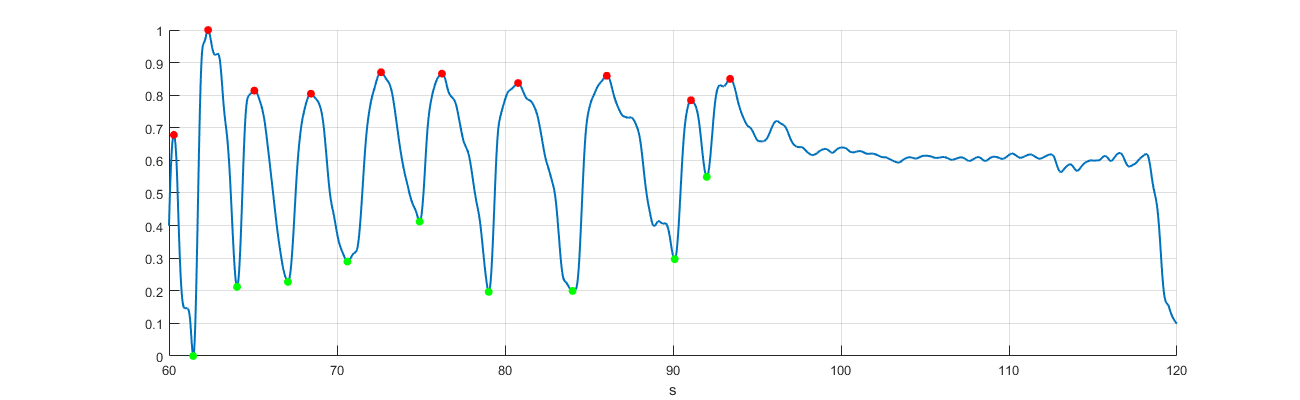

max_prom = 0.1;
max_dist = 100;

min_prom = 0.1; 
min_dist = 100;

[~, maxs] = findpeaks(s1,'MinPeakProminence', max_prom, 'MinPeakDistance', max_dist);  % maxima
[~, mins] = findpeaks(-s1,'MinPeakProminence', min_prom,'MinPeakDistance', min_dist);  % minima

f = figure(3); clf; hold on;
set(f, 'Position', [0 0 1300 400]);
plot(t, s1, 'LineWidth', 1.5);
scatter(t(maxs), s1(maxs),'r','filled');
scatter(t(mins), s1(mins),'g','filled');
xlabel('s');grid on;

### Tidal values

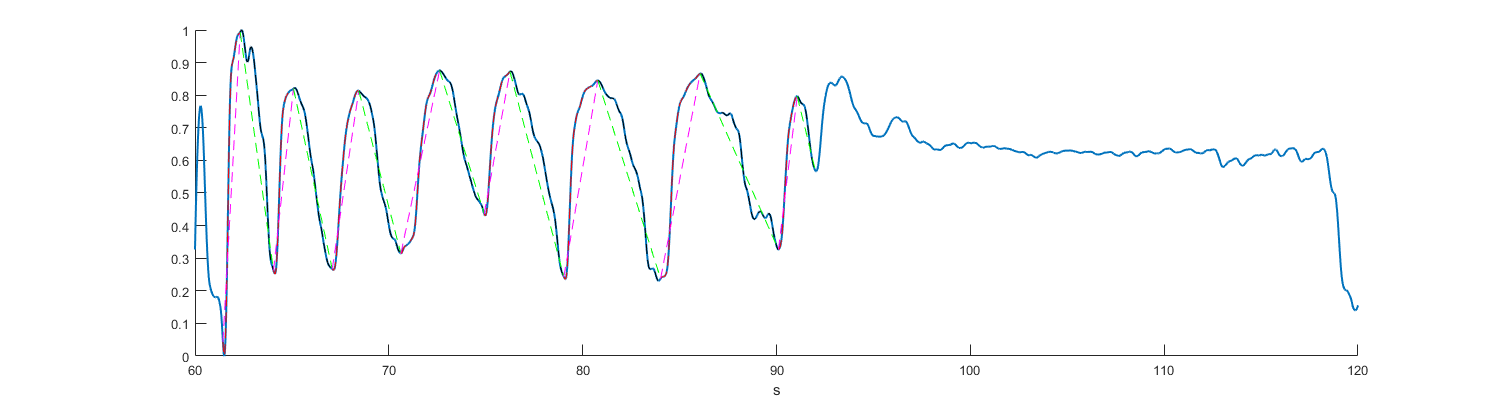

ds = abs(diff(s));  % for visualization


f = figure(4);clf;hold on;
set(f, 'Position', [0 0 1500 400]);
plot(t,s1,'LineWidth',1.5 );xlabel('s');

% Compute tidal times    
ii=1;
for j=1:length(mins)-1
        
    % Get minimum       
    x1 = mins(j);        
    t1 = t(x1);
    y1 = s1(x1);
    
    % Get next minimum
    x3 = mins(j+1);
    t3 = t(x3);
    y3 = s1(x3);
    
    % Find maximum between
    ind_max = find(maxs > x1 & maxs < x3);
    
    % No maxima found            
    if isempty(ind_max)
        warning('no minima found');
        continue;
    end        
    if length(ind_max)> 1
       warning('More than one maxima found');
       continue
    end
    
    x2 = maxs(ind_max);
    t2 = t(x2);
    y2 = s1(x2);
    
    % Upper part        
    x_up = x1:x2;
    t_up = t(x_up);
    y_up = s1(x_up);        
    y_up_c = (y2-y1)/(t2-t1)*(t_up -t1) + y1;  
    
    % Down part        
    x_down = x2:x3;
    t_down = t(x_down);
    y_down = s1(x_down);        
    y_down_c = (y3-y2)/(t3-t2)*(t_down -t2) + y2;  
    

    plot(t_up,y_up,'--r');
    plot(t_up,y_up_c,'--m');
    plot(t_down,y_down,'--k');
    plot(t_down,y_down_c,'--g');           
    
    met_up(ii) = mean(y_up - y_up_c');
    met_down(ii) = mean(y_down - y_down_c');
    ii = ii + 1;
end

disp(['Mean up: ' num2str(mean(met_up))])

Mean up: 0.078048


disp(['Mean down: ' num2str(mean(met_down))])

Mean down: 0.035913
